defaultDir = 'M:\Bergles Lab Data\Papers\In Vivo Paper'; %change if in a different location
cd(defaultDir);
addpath(genpath('MATLAB Functions'));
cd(['Figure 7 - VG3 Intrinsic Excitability']);


%load cells
cellList = loadFileList('.\Data\*\*Cell*.mat');

[h] = load(cellList{1})

h = struct with fields:
    expt: [1×1 struct]


names = fieldnames(h);
h.(names{1})

ans = struct with fields:
        mouseID: '501.10.4'
       mouseAge: 6
    mouseWeight: 3.2000
      mouseGeno: 'VG3het'
       cochTurn: 'Middle'
      dateOfExp: '20180504'
             Vm: -58.6253
            Tau: 38.6894
           file: [1×1 struct]
          ssRin: 626
          pkRin: 1339
        IVsteps: [17×1 double]
             rb: 51.6667
        maxdVdT: 0.6409
          APthr: -32.6416
       APheight: 45.7944
           temp: 24



cellStruct = struct();
Rpk_con = [];
Rss_con = [];
tau_con = [];
vm_con = [];
rb_con = [];
Rpk_VG3 = [];
Rss_VG3 = [];
tau_VG3 = [];
vm_VG3 = [];
rb_VG3 = [];

 for i = 1:size(cellList,1)
    [h] = load(cellList{i});
    names = fieldnames(h);
    temp = h.(names{1});
    if strcmp(temp.mouseGeno,'WT') | strcmp(temp.mouseGeno,'VG3het')
        Rpk_con = [Rpk_con; temp.pkRin];
        Rss_con = [Rss_con; temp.ssRin];
        tau_con = [tau_con; temp.Tau];
        vm_con = [vm_con; temp.Vm];
        rb_con = [rb_con; temp.rb];
    elseif strcmp(temp.mouseGeno,'VG3KO')
        if size(vm_VG3,1) == 3
            cellList{i}
        end
        Rpk_VG3 = [Rpk_VG3; temp.pkRin];
        Rss_VG3 = [Rss_VG3; temp.ssRin];
        tau_VG3 = [tau_VG3; temp.Tau];
        vm_VG3 = [vm_VG3; temp.Vm];
        rb_VG3 = [rb_VG3; temp.rb];
    else
        temp.mouseGeno
    end
    
 end

ans = 'M:\Bergles Lab Data\Papers\In Vivo Paper\Figure 7 - VG3 Intrinsic Excitability\Data\180504\20180504_Cell08.mat'


[h, p] = compare2(Rpk_con/1000,Rpk_VG3/1000,{'WT', 'VG3 KO'}, 'Rpk (G\Omega)', [1.5 2],[5 12]);

   6.4184e-04



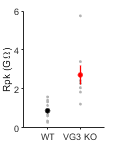

ylim([0 6]);
yticks(0:2:6);
axh = gca;
dim = [.9 1.5];
figQuality(gcf, axh, dim);
export_fig('.\EPS Panels\Rpk.eps',gcf);


[h, p] = compare2(Rss_con/1000,Rss_VG3/1000,{'WT', 'VG3 KO'}, 'Rss (G\Omega)', [1.5 2],[5 12]);

   1.0401e-05



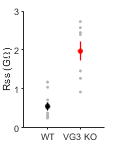

ylim([0 3]);
yticks(0:1:3);
axh = gca;
dim = [.9 1.5];
figQuality(gcf, axh, dim);
export_fig('.\EPS Panels\Rss.eps',gcf);


[h, p] = compare2(tau_con,tau_VG3,{'WT', 'VG3 KO'}, '\tau (ms)', [1.5 2],[5 12]);

   1.0558e-04



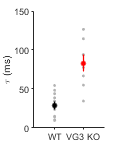

ylim([0 150]);
yticks(0:50:150);
axh = gca;
dim = [.9 1.5];
figQuality(gcf, axh, dim);
export_fig('.\EPS Panels\tau.eps',gcf);


[h, p] = compare2(vm_con,vm_VG3,{'WT', 'VG3 KO'}, 'Vm (mV)', [1.5 2],[5 12]);

    0.5010



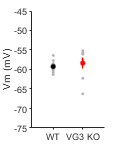

ylim([-75 -45])
axh = gca;
dim = [.9 1.5];
figQuality(gcf, axh, dim);
export_fig('.\EPS Panels\vm.eps',gcf);


[h, p] = compare2(rb_con,rb_VG3,{'WT', 'VG3 KO'}, 'Current Threshold (pA)', [1.5 2],[5 12]);

   3.2792e-04



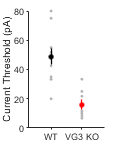

%ylim([-75 -45])
axh = gca;
dim = [.9 1.5];
figQuality(gcf, axh, dim);
export_fig('.\EPS Panels\rb.eps',gcf);

## Load all data into structure

%load cells
cellList = loadFileList('.\Data\*\*Cell*.mat');

for i = 1:size(cellList,1)
  [h] = load(cellList{i});
   names = fieldnames(h);
   temp = h.(names{1});
   if i == 1
    cellStruct(1) = temp;
   else
    cellStruct(i) = temp;
   end
end


genos = {cellStruct.mouseGeno};

VG3idx =      3     4     5     6    12    13    16    17    21    22    23    24    25    26    27    28    29    30    31


conidx =      1     2     7     8     9    10    11    14    15    18    19    20    32


VG3idx = find(contains(genos,'VG3KO'))
conidx = find(~contains(genos,'VG3KO'))

cell2mat({cellStruct(VG3idx).APheight})

ans =    32.9166   49.4444   52.7948   53.6890   43.0645   43.0362   47.0145   40.3141   53.3301   47.5626   37.4948   33.9571   47.5156   44.4134   50.6548   43.6903   50.9254   46.8827   51.7309


[h, p] = compare2(cell2mat({cellStruct(conidx).APheight})',cell2mat({cellStruct(VG3idx).APheight})',{'WT', 'VG3 KO'}, 'AP Height (mV)', [1.5 2],[5 12]);

    0.3281



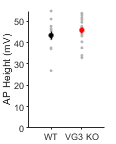

%ylim([-75 -45])
axh = gca;
dim = [.9 1.5];
figQuality(gcf, axh, dim);
export_fig('.\EPS Panels\rb.eps',gcf);


[h, p] = compare2([cellStruct(conidx).maxdVdT]',[cellStruct(VG3idx).maxdVdT]',{'WT', 'VG3 KO'}, 'Max dV/dT', [1.5 2],[5 12]);

    0.0281



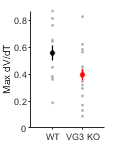

%ylim([-75 -45])
axh = gca;
dim = [.9 1.5];
figQuality(gcf, axh, dim);
export_fig('.\EPS Panels\rb.eps',gcf);


[h, p] = compare2([cellStruct(conidx).APthr]',[cellStruct(VG3idx).APthr]',{'WT', 'VG3 KO'}, 'AP Thr (mV)', [1.5 2],[5 12]);

    0.8323



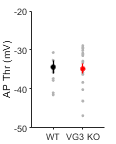

ylim([-50 -20])
axh = gca;
dim = [.9 1.5];
figQuality(gcf, axh, dim);
export_fig('.\EPS Panels\rb.eps',gcf);

genos = {cellStruct.mouseGeno};
VG3idxRT = find(contains(genos,'VG3KO') & [cellStruct.temp] == 24)

VG3idxRT =      3     4     5     6    12    13    16    17    27


conidxRT = find(~contains(genos,'VG3KO') & [cellStruct.temp] == 24)

conidxRT =      1     2     7     8     9    10    11    14    15


VG3idxPT = find(contains(genos,'VG3KO') & [cellStruct.temp] == 32)

VG3idxPT =     21    22    23    24    25    26    28    29    30    31


conidxPT = find(~contains(genos,'VG3KO') & [cellStruct.temp] == 32)

conidxPT =     18    19    20    32


dim = [0.7 1.3];
figure; 
[h, p] = compare4sp([cellStruct(conidxRT).pkRin]/1000,[cellStruct(VG3idxRT).pkRin]/1000,[cellStruct(conidxPT).pkRin]/1000,[cellStruct(VG3idxPT).pkRin]/1000,{'WT', 'VG3 KO'}, 'Rpk (G\Omega)', [1.5 2],[5 12],'k','r',1);

    0.0016

    0.0034



ylim([0 6]);
yticks(0:2:6);
axh = gca;
figQuality(gcf, axh, dim);
%export_fig('.\EPS Panels\Rpk.eps',gcf);

[h, p] = compare4sp([cellStruct(conidxRT).ssRin]/1000,[cellStruct(VG3idxRT).ssRin]/1000,[cellStruct(conidxPT).ssRin]/1000,[cellStruct(VG3idxPT).ssRin]/1000,{'WT', 'VG3 KO'}, 'Rss (G\Omega)', [1.5 2],[5 12],'k','r',2);

   2.4309e-05

    0.0016



ylim([0 3]);
yticks(0:1:3);
axh = gca;
figQuality(gcf, axh, dim);


[h, p] = compare4sp([cellStruct(conidxRT).Tau],[cellStruct(VG3idxRT).Tau],[cellStruct(conidxPT).Tau],[cellStruct(VG3idxPT).Tau],{'WT', 'VG3 KO'}, 'Tau (ms)', [1.5 2],[5 12],'k','r',3);

   7.5904e-05

    0.0366



ylim([0 150]);
yticks(0:50:150);
axh = gca;
figQuality(gcf, axh, dim);


[h, p] = compare4sp([cellStruct(conidxRT).Vm],[cellStruct(VG3idxRT).Vm],[cellStruct(conidxPT).Vm],[cellStruct(VG3idxPT).Vm],{'WT', 'VG3 KO'}, 'Vm (mV)', [1.5 2],[5 12],'k','r',4);

    0.3433

    0.9210



ylim([-70 -50])
yticks(-70:10:-50)
axh = gca;
figQuality(gcf, axh, dim);


[h, p] = compare4sp([cellStruct(conidxRT).rb],[cellStruct(VG3idxRT).rb],[cellStruct(conidxPT).rb],[cellStruct(VG3idxPT).rb],{'WT', 'VG3 KO'}, 'Current Threshold (pA)', [1.5 2],[5 12],'k','r',5);

   1.6966e-04

    0.0070



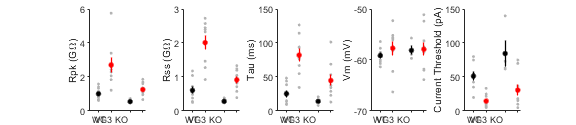

ylim([0 150]);
yticks(0:50:150);
axh = gca;
figQuality(gcf, axh, dim);

figQuality(gcf, axh, [6 1.3]);
export_fig('.\EPS Panels\intrinsic_props.eps',gcf);

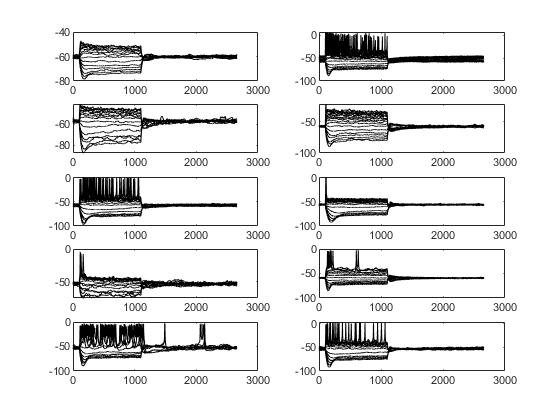

opening M:\Bergles Lab Data\Papers\In Vivo Paper\Figure 7 - VG3 Intrinsic Excitability\Data\180510\18510057.abf..
**** available channels:
    'IN 0'

data were acquired in waveform fixed-length mode


opening M:\Bergles Lab Data\Papers\In Vivo Paper\Figure 7 - VG3 Intrinsic Excitability\Data\180510\18510071.abf..
**** available channels:
    'IN 0'

data were acquired in waveform fixed-length mode


opening M:\Bergles Lab Data\Papers\In Vivo Paper\Figure 7 - VG3 Intrinsic Excitability\Data\180510\18510079.abf..
**** available channels:
    'IN 0'

data were acquired in waveform fixed-length mode


opening M:\Bergles Lab Data\Papers\In Vivo Paper\Figure 7 - VG3 Intrinsic Excitability\Data\180510\18510086.abf..
**** available channels:
    'IN 0'

data were acquired in waveform fixed-length mode


opening M:\Bergles Lab Data\Papers\In Vivo Paper\Figure 7 - VG3 Intrinsic Excitability\Data\180514\18514006.abf..
**** available channels:
    'IN 0'

data were acquired in waveform fixed-length mode


opening M:\Bergles Lab Data\Papers\In Vivo Paper\Figure 7 - VG3 Intrinsic Excitability\Data\180514\18514014.abf..
**** available channels:
    'IN 0'

data were acquired in waveform fixed-length mode


opening M:\Bergles Lab Data\Papers\In Vivo Paper\Figure 7 - VG3 Intrinsic Excitability\Data\180514\18514029.abf..
**** available channels:
    'IN 0'

data were acquired in waveform fixed-length mode


opening M:\Bergles Lab Data\Papers\In Vivo Paper\Figure 7 - VG3 Intrinsic Excitability\Data\180514\18514040.abf..
**** available channels:
    'IN 0'

data were acquired in waveform fixed-length mode


opening M:\Bergles Lab Data\Papers\In Vivo Paper\Figure 7 - VG3 Intrinsic Excitability\Data\180514\18514048.abf..
**** available channels:
    'IN 0'

data were acquired in waveform fixed-length mode


opening M:\Bergles Lab Data\Papers\In Vivo Paper\Figure 7 - VG3 Intrinsic Excitability\Data\180514\18514058.abf..
**** available channels:
    'IN 0'

data were acquired in waveform fixed-length mode


%load IVs for PT VG3 KO
figure;
for i=1:size(VG3idxPT,2)
    temp = cellStruct(VG3idxPT(i)).file;
    file = temp(1).IV;
    subplot(5,2,i);
    file = loadFileList(['.\Data\*\' file]);
    [d,time]=abfloadClean(file{1});
    plot(time,d,'k');
    
end

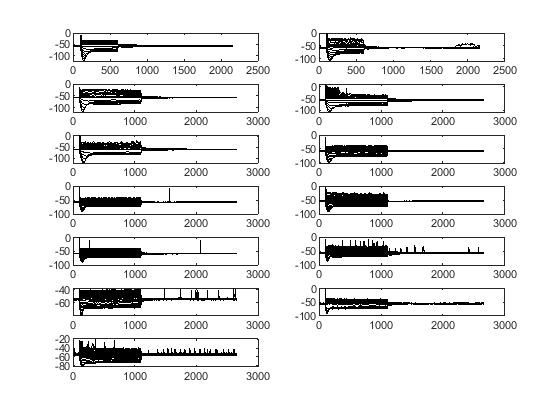

opening M:\Bergles Lab Data\Papers\In Vivo Paper\Figure 7 - VG3 Intrinsic Excitability\Data\180504\18504016.abf..
**** available channels:
    'IN 0'

data were acquired in waveform fixed-length mode


opening M:\Bergles Lab Data\Papers\In Vivo Paper\Figure 7 - VG3 Intrinsic Excitability\Data\180504\18504022.abf..
**** available channels:
    'IN 0'

data were acquired in waveform fixed-length mode


opening M:\Bergles Lab Data\Papers\In Vivo Paper\Figure 7 - VG3 Intrinsic Excitability\Data\180504\18504073.abf..
**** available channels:
    'IN 0'

data were acquired in waveform fixed-length mode


opening M:\Bergles Lab Data\Papers\In Vivo Paper\Figure 7 - VG3 Intrinsic Excitability\Data\180504\18504081.abf..
**** available channels:
    'IN 0'

data were acquired in waveform fixed-length mode


opening M:\Bergles Lab Data\Papers\In Vivo Paper\Figure 7 - VG3 Intrinsic Excitability\Data\180504\18504087.abf..
**** available channels:
    'IN 0'

data were acquired in waveform fixed-length mode


opening M:\Bergles Lab Data\Papers\In Vivo Paper\Figure 7 - VG3 Intrinsic Excitability\Data\180505\18505003.abf..
**** available channels:
    'IN 0'

data were acquired in waveform fixed-length mode


opening M:\Bergles Lab Data\Papers\In Vivo Paper\Figure 7 - VG3 Intrinsic Excitability\Data\180505\18505009.abf..
**** available channels:
    'IN 0'

data were acquired in waveform fixed-length mode


opening M:\Bergles Lab Data\Papers\In Vivo Paper\Figure 7 - VG3 Intrinsic Excitability\Data\180505\18505039.abf..
**** available channels:
    'IN 0'

data were acquired in waveform fixed-length mode


opening M:\Bergles Lab Data\Papers\In Vivo Paper\Figure 7 - VG3 Intrinsic Excitability\Data\180505\18505047.abf..
**** available channels:
    'IN 0'

data were acquired in waveform fixed-length mode


opening M:\Bergles Lab Data\Papers\In Vivo Paper\Figure 7 - VG3 Intrinsic Excitability\Data\180510\18510005.abf..
**** available channels:
    'IN 0'

data were acquired in waveform fixed-length mode


opening M:\Bergles Lab Data\Papers\In Vivo Paper\Figure 7 - VG3 Intrinsic Excitability\Data\180510\18510036.abf..
**** available channels:
    'IN 0'

data were acquired in waveform fixed-length mode


opening M:\Bergles Lab Data\Papers\In Vivo Paper\Figure 7 - VG3 Intrinsic Excitability\Data\180510\18510049.abf..
**** available channels:
    'IN 0'

data were acquired in waveform fixed-length mode


opening M:\Bergles Lab Data\Papers\In Vivo Paper\Figure 7 - VG3 Intrinsic Excitability\Data\180514\18514066.abf..
**** available channels:
    'IN 0'

data were acquired in waveform fixed-length mode



figure;
for i=1:size(conidx,2)
    temp = cellStruct(conidx(i)).file;
    file = temp(1).IV;
    subplot(7,2,i);
    file = loadFileList(['.\Data\*\' file]);
    [d,time]=abfloadClean(file{1});
    plot(time,d,'k');
    
end

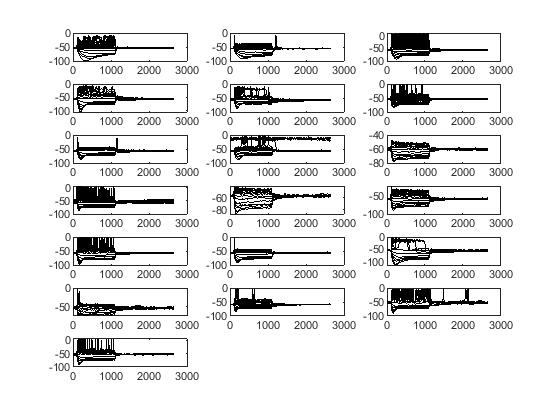

opening M:\Bergles Lab Data\Papers\In Vivo Paper\Figure 7 - VG3 Intrinsic Excitability\Data\180504\18504033.abf..
**** available channels:
    'IN 0'

data were acquired in waveform fixed-length mode


opening M:\Bergles Lab Data\Papers\In Vivo Paper\Figure 7 - VG3 Intrinsic Excitability\Data\180504\18504039.abf..
**** available channels:
    'IN 0'

data were acquired in waveform fixed-length mode


opening M:\Bergles Lab Data\Papers\In Vivo Paper\Figure 7 - VG3 Intrinsic Excitability\Data\180504\18504058.abf..
**** available channels:
    'IN 0'

data were acquired in waveform fixed-length mode


opening M:\Bergles Lab Data\Papers\In Vivo Paper\Figure 7 - VG3 Intrinsic Excitability\Data\180504\18504064.abf..
**** available channels:
    'IN 0'

data were acquired in waveform fixed-length mode


opening M:\Bergles Lab Data\Papers\In Vivo Paper\Figure 7 - VG3 Intrinsic Excitability\Data\180505\18505014.abf..
**** available channels:
    'IN 0'

data were acquired in waveform fixed-length mode


opening M:\Bergles Lab Data\Papers\In Vivo Paper\Figure 7 - VG3 Intrinsic Excitability\Data\180505\18505028.abf..
**** available channels:
    'IN 0'

data were acquired in waveform fixed-length mode


opening M:\Bergles Lab Data\Papers\In Vivo Paper\Figure 7 - VG3 Intrinsic Excitability\Data\180505\18505053.abf..
**** available channels:
    'IN 0'

data were acquired in waveform fixed-length mode


opening M:\Bergles Lab Data\Papers\In Vivo Paper\Figure 7 - VG3 Intrinsic Excitability\Data\180505\18505061.abf..
**** available channels:
    'IN 0'

data were acquired in waveform fixed-length mode


opening M:\Bergles Lab Data\Papers\In Vivo Paper\Figure 7 - VG3 Intrinsic Excitability\Data\180510\18510057.abf..
**** available channels:
    'IN 0'

data were acquired in waveform fixed-length mode


opening M:\Bergles Lab Data\Papers\In Vivo Paper\Figure 7 - VG3 Intrinsic Excitability\Data\180510\18510071.abf..
**** available channels:
    'IN 0'

data were acquired in waveform fixed-length mode


opening M:\Bergles Lab Data\Papers\In Vivo Paper\Figure 7 - VG3 Intrinsic Excitability\Data\180510\18510079.abf..
**** available channels:
    'IN 0'

data were acquired in waveform fixed-length mode


opening M:\Bergles Lab Data\Papers\In Vivo Paper\Figure 7 - VG3 Intrinsic Excitability\Data\180510\18510086.abf..
**** available channels:
    'IN 0'

data were acquired in waveform fixed-length mode


opening M:\Bergles Lab Data\Papers\In Vivo Paper\Figure 7 - VG3 Intrinsic Excitability\Data\180514\18514006.abf..
**** available channels:
    'IN 0'

data were acquired in waveform fixed-length mode


opening M:\Bergles Lab Data\Papers\In Vivo Paper\Figure 7 - VG3 Intrinsic Excitability\Data\180514\18514014.abf..
**** available channels:
    'IN 0'

data were acquired in waveform fixed-length mode


opening M:\Bergles Lab Data\Papers\In Vivo Paper\Figure 7 - VG3 Intrinsic Excitability\Data\180514\18514022.abf..
**** available channels:
    'IN 0'

data were acquired in waveform fixed-length mode


opening M:\Bergles Lab Data\Papers\In Vivo Paper\Figure 7 - VG3 Intrinsic Excitability\Data\180514\18514029.abf..
**** available channels:
    'IN 0'

data were acquired in waveform fixed-length mode


opening M:\Bergles Lab Data\Papers\In Vivo Paper\Figure 7 - VG3 Intrinsic Excitability\Data\180514\18514040.abf..
**** available channels:
    'IN 0'

data were acquired in waveform fixed-length mode


opening M:\Bergles Lab Data\Papers\In Vivo Paper\Figure 7 - VG3 Intrinsic Excitability\Data\180514\18514048.abf..
**** available channels:
    'IN 0'

data were acquired in waveform fixed-length mode


opening M:\Bergles Lab Data\Papers\In Vivo Paper\Figure 7 - VG3 Intrinsic Excitability\Data\180514\18514058.abf..
**** available channels:
    'IN 0'

data were acquired in waveform fixed-length mode



figure;
for i=1:size(VG3idx,2)
    temp = cellStruct(VG3idx(i)).file;
    file = temp(1).IV;
    subplot(7,3,i);
    file = loadFileList(['.\Data\*\' file]);
    [d,time]=abfloadClean(file{1});
    plot(time,d,'k');
    
end


figure;
i = 2;
temp = cellStruct(VG3idxPT(i)).file;
    file = temp(1).IV;
    file = loadFileList(['.\Data\*\' file]);
    [d,time]=abfloadClean(file{1});

opening M:\Bergles Lab Data\Papers\In Vivo Paper\Figure 7 - VG3 Intrinsic Excitability\Data\180510\18510071.abf..
**** available channels:
    'IN 0'

data were acquired in waveform fixed-length mode


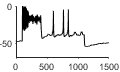

    plot(time,d(:,22),'k');
    xlim([0 1500]);
    ylim([-70 0])
    figQuality(gcf,gca,[1.25 0.75])
    export_fig('.\EPS Panels\VG3_step.eps',gcf);

    cellStruct(VG3idxPT(i)).IVsteps(22)

ans = 75

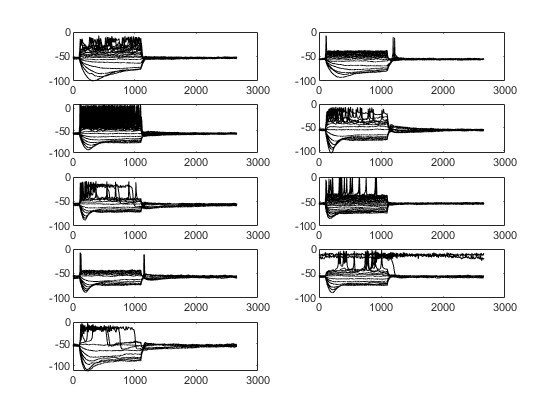

opening M:\Bergles Lab Data\Papers\In Vivo Paper\Figure 7 - VG3 Intrinsic Excitability\Data\180504\18504033.abf..
**** available channels:
    'IN 0'

data were acquired in waveform fixed-length mode


opening M:\Bergles Lab Data\Papers\In Vivo Paper\Figure 7 - VG3 Intrinsic Excitability\Data\180504\18504039.abf..
**** available channels:
    'IN 0'

data were acquired in waveform fixed-length mode


opening M:\Bergles Lab Data\Papers\In Vivo Paper\Figure 7 - VG3 Intrinsic Excitability\Data\180504\18504058.abf..
**** available channels:
    'IN 0'

data were acquired in waveform fixed-length mode


opening M:\Bergles Lab Data\Papers\In Vivo Paper\Figure 7 - VG3 Intrinsic Excitability\Data\180504\18504064.abf..
**** available channels:
    'IN 0'

data were acquired in waveform fixed-length mode


opening M:\Bergles Lab Data\Papers\In Vivo Paper\Figure 7 - VG3 Intrinsic Excitability\Data\180505\18505014.abf..
**** available channels:
    'IN 0'

data were acquired in waveform fixed-length mode


opening M:\Bergles Lab Data\Papers\In Vivo Paper\Figure 7 - VG3 Intrinsic Excitability\Data\180505\18505028.abf..
**** available channels:
    'IN 0'

data were acquired in waveform fixed-length mode


opening M:\Bergles Lab Data\Papers\In Vivo Paper\Figure 7 - VG3 Intrinsic Excitability\Data\180505\18505053.abf..
**** available channels:
    'IN 0'

data were acquired in waveform fixed-length mode


opening M:\Bergles Lab Data\Papers\In Vivo Paper\Figure 7 - VG3 Intrinsic Excitability\Data\180505\18505061.abf..
**** available channels:
    'IN 0'

data were acquired in waveform fixed-length mode


opening M:\Bergles Lab Data\Papers\In Vivo Paper\Figure 7 - VG3 Intrinsic Excitability\Data\180514\18514022.abf..
**** available channels:
    'IN 0'

data were acquired in waveform fixed-length mode


%load IVs for RT VG3 KO
figure;
for i=1:size(VG3idxRT,2)
    temp = cellStruct(VG3idxRT(i)).file;
    file = temp(1).IV;
    subplot(5,2,i);
    file = loadFileList(['.\Data\*\' file]);
    [d,time]=abfloadClean(file{1});
    plot(time,d,'k');
    
end

figure;
i = 9;
temp = cellStruct(VG3idxRT(i)).file;
    file = temp(1).IV;
    file = loadFileList(['.\Data\*\' file]);
    [d,time]=abfloadClean(file{1});

opening M:\Bergles Lab Data\Papers\In Vivo Paper\Figure 7 - VG3 Intrinsic Excitability\Data\180514\18514022.abf..
**** available channels:
    'IN 0'

data were acquired in waveform fixed-length mode


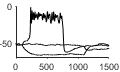

    plot(time,d(:,6:8),'k');
    xlim([0 1500]);
    ylim([-70 0])
    figQuality(gcf,gca,[1.25 0.75])
    export_fig('.\EPS Panels\VG3_step_2.eps',gcf);

    %cellStruct(VG3idxRT(i)).IVsteps(22)
file

file = 1×1 cell array
    {'M:\Bergles Lab Data\Papers\In Vivo Paper\Figure 7 - VG3 Intrinsic Excitability\Data\180514\18514022.abf'}


%Example VG3KO trace
file = '18514058';
file = loadFileList(['.\Data\*\' file '.abf']);
[d,time] = abfloadClean(file{1});

opening M:\Bergles Lab Data\Papers\In Vivo Paper\Figure 7 - VG3 Intrinsic Excitability\Data\180514\18514058.abf..
**** available channels:
    'IN 0'

data were acquired in waveform fixed-length mode


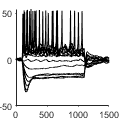

meanD = mean(d(1:100,:),1);
figure;
plot(time,d(:,1:1:15)-meanD(1:15),'k');
xlim([0 1500]);
figQuality(gcf,gca,[1.25 1.25]);
export_fig('.\EPS Panels\VG3_IV.eps',gcf);



startpA = -30;
steppA = 5;
endpA = 40;
steps = [startpA:steppA:endpA]';
stepLength = 1000;
stepStart = 100; % ms

startVm = [];
ssVm = [];
pkVm = [];
for i=1:size(steps,1)
    startVm(i) = mean(d(time < 100,i)); %first 100ms
    ssVm(i) = mean(d(time > stepStart + stepLength - 100 & time < stepStart + stepLength,i));
    if steps(i) <= 0
       pkVm(i) = min(d(time > stepStart & time < stepStart + stepLength/2,i));
    else
        pkVm(i) = max(d(time > stepStart & time < stepStart + stepLength/2,i));
        if pkVm(i) > -40 %%if spike detected
            pkVm(i) = NaN; 
        end
    end
end

ss = [ssVm - startVm]';
pk = [pkVm - startVm]';
stepBoolss = (ss > -15.57 & ss <= 2) & steps <= 0;
stepBoolpk = (pk > -20 & pk <= 2) & steps <= 0;

f = @(m,x,b) m*x+b;
[mss,bss] = leastSquares(steps(stepBoolss),ss(stepBoolss));
[mpk,bpk] = leastSquares(steps(stepBoolpk),pk(stepBoolpk));

%MATLAB2016 or higher
% startPts = [0 .2] %guesses for fit
% fitss = fit(steps(stepBoolss),ss(stepBoolss),'a*x+b','StartPoint',startPts);
% fitpk = fit(steps(stepBoolpk),pk(stepBoolpk),'a*x+b','StartPoint',startPts);



%plot the data
figure;
subplot(1,2,1);
lgrey = [0.8 0.8 0.8];
hold on; plot(time,d(:,1:13)-meanD(1:13),'Color','k');
xlim([0 1500]);
ylim([-40 50]);

subplot(1,2,2);
plot(steps, ssVm - startVm,'o','Color','k','MarkerSize',3,'LineWidth',0.5)
hold on;
plot(steps, pkVm - startVm,'^','Color','k','MarkerSize',3,'MarkerFaceColor',[0.8 0.8 0.8],'LineWidth',0.5)
plot(steps(stepBoolss),steps(stepBoolss)*mss + bss,'Color','k');
plot(steps(stepBoolpk),steps(stepBoolpk)*mpk + bpk,'Color','k');
box off;
ax = gca;
%ax.XAxisLocation = 'origin';
%ax.YAxisLocation = 'origin';
xlim([-60 30]);
xticks([-60:30:30]);
ylim([-40 20]);

%%%%expt.pkRin = round(mpk * 10^3); %megaohms

%dim = [0.7 0.0 0.5 0.5];
%str = {['Rss: ' num2str(expt.ssRin) ' M\Omega'],['Rpk: ' num2str(expt.pkRin) ' M\Omega']};
%annotation('textbox',dim,'String',str,'FitBoxToText','on');
figh = gcf;
figh.Units = 'inches'

figh =   Figure (15) with properties:

      Number: 15
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [10.4063 9.5521 5.8333 4.3750]
       Units: 'inches'

  Show all properties


dim = [3.2 1.3]

dim =     3.2000    1.3000


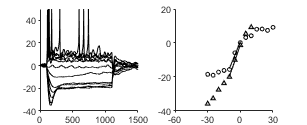

figh.Position = [0 0 dim];
figQuality(gcf,gca,dim);
export_fig('.\EPS Panels\VG3_fullIV.eps',gcf);

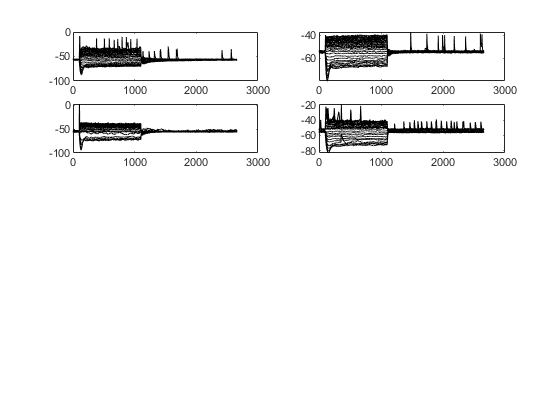

file = '18510005.abf'

opening M:\Bergles Lab Data\Papers\In Vivo Paper\Figure 7 - VG3 Intrinsic Excitability\Data\180510\18510005.abf..
**** available channels:
    'IN 0'

data were acquired in waveform fixed-length mode


file = '18510036.abf'

opening M:\Bergles Lab Data\Papers\In Vivo Paper\Figure 7 - VG3 Intrinsic Excitability\Data\180510\18510036.abf..
**** available channels:
    'IN 0'

data were acquired in waveform fixed-length mode


file = '18510049.abf'

opening M:\Bergles Lab Data\Papers\In Vivo Paper\Figure 7 - VG3 Intrinsic Excitability\Data\180510\18510049.abf..
**** available channels:
    'IN 0'

data were acquired in waveform fixed-length mode


file = '18514066.abf'

opening M:\Bergles Lab Data\Papers\In Vivo Paper\Figure 7 - VG3 Intrinsic Excitability\Data\180514\18514066.abf..
**** available channels:
    'IN 0'

data were acquired in waveform fixed-length mode


%load IVs for PT VG3 het
figure;
for i=1:size(conidxPT,2)
    temp = cellStruct(conidxPT(i)).file;
    file = temp(1).IV
    subplot(5,2,i);
    file = loadFileList(['.\Data\*\' file]);
    [d,time]=abfloadClean(file{1});
    plot(time,d,'k');
    
end

file = '18510005';
file = loadFileList(['.\Data\*\' file '.abf']);
[d,time] = abfloadClean(file{1});

opening M:\Bergles Lab Data\Papers\In Vivo Paper\Figure 7 - VG3 Intrinsic Excitability\Data\180510\18510005.abf..
**** available channels:
    'IN 0'

data were acquired in waveform fixed-length mode


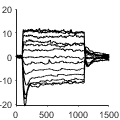

meanD = mean(d(1:100,:),1);
figure;
plot(time,d(:,5:1:17)-meanD(5:17),'k');
xlim([0 1500]);
figQuality(gcf,gca,[1.25 1.25]);
export_fig('.\EPS Panels\WT_IV.eps',gcf);


startpA = -50;
steppA = 5;
endpA = 40;
steps = [startpA:steppA:endpA]';
stepLength = 1000;
stepStart = 100; % ms

startVm = [];
ssVm = [];
pkVm = [];
for i=1:size(steps,1)
    startVm(i) = mean(d(time < 100,i)); %first 100ms
    ssVm(i) = mean(d(time > stepStart + stepLength - 100 & time < stepStart + stepLength,i));
    if steps(i) <= 0
       pkVm(i) = min(d(time > stepStart & time < stepStart + stepLength/2,i));
    else
        pkVm(i) = max(d(time > stepStart & time < stepStart + stepLength/2,i));
        if pkVm(i) > -40 %%if spike detected
            pkVm(i) = NaN; 
        end
    end
end

ss = [ssVm - startVm]';
pk = [pkVm - startVm]';
stepBoolss = (ss > -10 & ss <= 2) & steps <= 0;
stepBoolpk = (pk > -20 & pk <= 2) & steps <= 0;

f = @(m,x,b) m*x+b;
[mss,bss] = leastSquares(steps(stepBoolss),ss(stepBoolss));
[mpk,bpk] = leastSquares(steps(stepBoolpk),pk(stepBoolpk));

%MATLAB2016 or higher
% startPts = [0 .2] %guesses for fit
% fitss = fit(steps(stepBoolss),ss(stepBoolss),'a*x+b','StartPoint',startPts);
% fitpk = fit(steps(stepBoolpk),pk(stepBoolpk),'a*x+b','StartPoint',startPts);



%plot the data
figure;
subplot(1,2,1);
lgrey = [0.8 0.8 0.8];
hold on; plot(time,d(:,5:1:17)-meanD(5:17),'Color','k');
xlim([0 1500]);
ylim([-40 50]);

subplot(1,2,2);
plot(steps, ssVm - startVm,'o','Color','k','MarkerSize',3,'LineWidth',0.5)
hold on;
plot(steps, pkVm - startVm,'^','Color','k','MarkerSize',3,'MarkerFaceColor',[0.8 0.8 0.8],'LineWidth',0.5)
plot(steps(stepBoolss),steps(stepBoolss)*mss + bss,'Color','k');
plot(steps(stepBoolpk),steps(stepBoolpk)*mpk + bpk,'Color','k');
box off;
ax = gca;
%ax.XAxisLocation = 'origin';
%ax.YAxisLocation = 'origin';
xlim([-60 30]);
xticks([-60:30:30]);
ylim([-40 20]);

%%%%expt.pkRin = round(mpk * 10^3); %megaohms

%dim = [0.7 0.0 0.5 0.5];
%str = {['Rss: ' num2str(expt.ssRin) ' M\Omega'],['Rpk: ' num2str(expt.pkRin) ' M\Omega']};
%annotation('textbox',dim,'String',str,'FitBoxToText','on');
figh = gcf;
figh.Units = 'inches'

figh =   Figure (82) with properties:

      Number: 82
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [10.4063 9.5521 5.8333 4.3750]
       Units: 'inches'

  Show all properties


dim = [3.2 1.3]

dim =     3.2000    1.3000


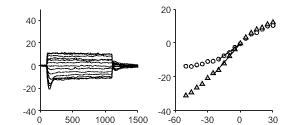

figh =   Figure (82) with properties:

      Number: 82
        Name: ''
       Color: [1 1 1]
    Position: [0 0 3.2000 1.3000]
       Units: 'inches'

  Show all properties


dim =     3.2000    1.3000


figh.Position = [0 0 dim];
figQuality(gcf,gca,dim);
export_fig('.\EPS Panels\con_abbIV.eps',gcf);




%plot the data
figure;
subplot(1,2,1);
lgrey = [0.8 0.8 0.8];
hold on; plot(time,d(:,1:2:end-1)-meanD(1:2:end-1),'Color','k');
xlim([0 1500]);
ylim([-40 50]);

subplot(1,2,2);
plot(steps, ssVm - startVm,'o','Color','k','MarkerSize',3,'LineWidth',0.5)
hold on;
plot(steps, pkVm - startVm,'^','Color','k','MarkerSize',3,'MarkerFaceColor',[0.8 0.8 0.8],'LineWidth',0.5)
plot(steps(stepBoolss),steps(stepBoolss)*mss + bss,'Color','k');
plot(steps(stepBoolpk),steps(stepBoolpk)*mpk + bpk,'Color','k');
box off;
ax = gca;
%ax.XAxisLocation = 'origin';
%ax.YAxisLocation = 'origin';
xlim([-60 30]);
xticks([-60:30:30]);
ylim([-40 20]);

%%%%expt.pkRin = round(mpk * 10^3); %megaohms

%dim = [0.7 0.0 0.5 0.5];
%str = {['Rss: ' num2str(expt.ssRin) ' M\Omega'],['Rpk: ' num2str(expt.pkRin) ' M\Omega']};
%annotation('textbox',dim,'String',str,'FitBoxToText','on');
figh = gcf;
figh.Units = 'inches'

figh =   Figure (83) with properties:

      Number: 83
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [10.4063 9.5521 5.8333 4.3750]
       Units: 'inches'

  Show all properties


dim = [3.2 1.3]

dim =     3.2000    1.3000


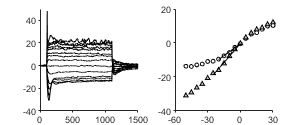

figh.Position = [0 0 dim];
figQuality(gcf,gca,dim);
export_fig('.\EPS Panels\con_fullIV.eps',gcf);

%taus
file = '18514056'; %VG3
file = loadFileList(['.\Data\*\' file '.abf']);
[d,time] = abfloadClean(file{1});

opening M:\Bergles Lab Data\Papers\In Vivo Paper\Figure 7 - VG3 Intrinsic Excitability\Data\180514\18514056.abf..
**** available channels:
    'IN 0'

data were acquired in waveform fixed-length mode


expt.Vm = mean(d(time(:,1) < 10),1); %baseline Vm

%find index of 10 and 90% of drop 
minTrace = min(d);
delta = minTrace - expt.Vm;
idx10 = find(d < (expt.Vm+.1*delta),1);
idx90 = find(d < (expt.Vm+.9*delta),1);

figure; 
plot(time,d,'Color','k'); hold on;
xlim([0 150]);
ylim([minTrace-1 expt.Vm+1])
f = @(b,x) b(1).*exp(-b(2).*x) + b(3);
nrmrsd = @(b) norm(d(idx10:idx90) - f(b,time(idx10:idx90)))                          % Residual Norm Cost Function

nrmrsd = function_handle with value:
    @(b)norm(d(idx10:idx90)-f(b,time(idx10:idx90)))


B0 = rand(3,1);
B0 = [10 .15 -50]% Choose Appropriate Initial Estimates

B0 =    10.0000    0.1500  -50.0000


[B,rnrm] = fminsearch(nrmrsd, B0) % Estimate Parameters ‘B’

B =    12.0872    0.0099  -69.3953


rnrm = 1.3941


estY = f(B,time(idx10:idx90));
plot(time(idx10:idx90),estY);
expt.Tau = 1/B(2)

expt = struct with fields:
     Vm: -58.5030
    Tau: 101.4124


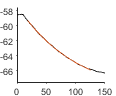

figQuality(gcf,gca,[1 1]);
export_fig('.\EPS Panels\VG3_tau.eps',gcf);



file = '18514000'; %VG3
file = loadFileList(['.\Data\*\' file '.abf']);
[d,time] = abfloadClean(file{1});

opening M:\Bergles Lab Data\Papers\In Vivo Paper\Figure 7 - VG3 Intrinsic Excitability\Data\180514\18514000.abf..
**** available channels:
    'IN 0'

data were acquired in waveform fixed-length mode


expt.Vm = mean(d(time(:,1) < 10),1); %baseline Vm

%find index of 10 and 90% of drop 
minTrace = min(d);
delta = minTrace - expt.Vm;
idx10 = find(d < (expt.Vm+.1*delta),1);
idx90 = find(d < (expt.Vm+.9*delta),1);

figure; 
plot(time,d,'Color','k'); hold on;
xlim([0 150]);
ylim([minTrace-1 expt.Vm+1])

f = @(b,x) b(1).*exp(-b(2).*x) + b(3);
nrmrsd = @(b) norm(d(idx10:idx90) - f(b,time(idx10:idx90)))                          % Residual Norm Cost Function

nrmrsd = function_handle with value:
    @(b)norm(d(idx10:idx90)-f(b,time(idx10:idx90)))


B0 = rand(3,1);
B0 = [10 .15 -50]% Choose Appropriate Initial Estimates

B0 =    10.0000    0.1500  -50.0000


[B,rnrm] = fminsearch(nrmrsd, B0) % Estimate Parameters ‘B’

B =     5.0653    0.0284  -57.2990


rnrm = 1.2626


estY = f(B,time(idx10:idx90));
plot(time(idx10:idx90),estY);
expt.Tau = 1/B(2)

expt = struct with fields:
     Vm: -53.4691
    Tau: 35.2383


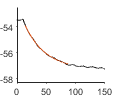

figQuality(gcf,gca,[1 1]);
export_fig('.\EPS Panels\WT_tau.eps',gcf);

## Example IV

control_file = '18510010';
file = loadFileList(['.\Data\*\' control_file '.abf']);
[d,time] = abfloadClean(file{1});

opening M:\Bergles Lab Data\Papers\In Vivo Paper\Figure 7 - VG3 Intrinsic Excitability\Data\180510\18510010.abf..
**** available channels:
    'IN 0'

data were acquired in gap-free mode
total length of recording: 301.4 s ~ 5 min
sampling interval: 20 µs
memory requirement for complete upload in matlab: 115 MB


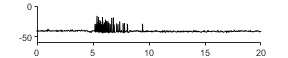

time = time/1000;
ts = 10;
te = 30;
%figure; plot(time,d)
figure; plot(time(time > ts & time < te)-time(time == ts),d(time > ts & time < te),'k')
ylim([-60 0]);
figQuality(gcf,gca,[3 0.6])
export_fig('.\EPS Panels\con_burst.eps',gcf);



vg3_file = '18514054';
file = loadFileList(['.\Data\*\' vg3_file '.abf']);
[d,time] = abfloadClean(file{1});

opening M:\Bergles Lab Data\Papers\In Vivo Paper\Figure 7 - VG3 Intrinsic Excitability\Data\180514\18514054.abf..
**** available channels:
    'IN 0'

data were acquired in gap-free mode
total length of recording: 302.4 s ~ 5 min
sampling interval: 20 µs
memory requirement for complete upload in matlab: 115 MB


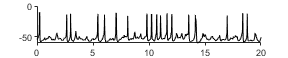

time = time/1000;
ts = 40;
te = 60;
figure; plot(time(time > ts & time < te)-time(time == ts),d(time > ts & time < te),'k')
ylim([-60 0]);
figQuality(gcf,gca,[3 0.6])
export_fig('.\EPS Panels\vg3_burst.eps',gcf);


vg3_file = '18514026';
file = loadFileList(['.\Data\*\' vg3_file '.abf']);
[d,si] = abfload(file{1});

opening M:\Bergles Lab Data\Papers\In Vivo Paper\Figure 7 - VG3 Intrinsic Excitability\Data\180514\18514026.abf..
**** available channels:
    'IN 0'

data were acquired in gap-free mode
total length of recording: 355.0 s ~ 6 min
sampling interval: 20 µs
memory requirement for complete upload in matlab: 135 MB


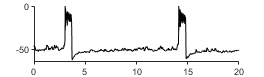

time = [0:1:size(d,1)]*si*10^-6;
ts = 0;
te = 20;
figure; plot(time(time > ts & time < te)-time(time == ts),d(time > ts & time < te),'k')
ylim([-65 0]);
figQuality(gcf,gca,[2.75 0.8])
export_fig('.\EPS Panels\vg3_burst.eps',gcf);



vg3_file = '18504031';
file = loadFileList(['.\Data\*\' vg3_file '.abf']);
[d,si] = abfload(file{1});

opening M:\Bergles Lab Data\Papers\In Vivo Paper\Figure 7 - VG3 Intrinsic Excitability\Data\180504\18504031.abf..
**** available channels:
    'IN 0'

data were acquired in waveform fixed-length mode


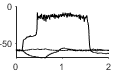

d = squeeze(d);
time = [0:1:size(d,1)]*si*10^-6;
ts = 0;
te = 2.1;
figure; plot(time(time > ts & time < te)-time(time == ts),d(time > ts & time < te,[10 11 17]),'k')
xlim([0 2]);
    ylim([-70 0])
    figQuality(gcf,gca,[1.25 0.75])
export_fig('.\EPS Panels\vg3_outlastStim.eps',gcf);